clear all

load 'C:\SortingFolder\HIP\NormalizedIndexesTableMUA.mat';
load 'C:\SortingFolder\HIP\SignificanceWindowTableMUA.mat'; %The matrix obtained from the fuction ExtractMatFiles.m
load 'C:\SortingFolder\HIP\NormalizedIndexesTable.mat';
load 'C:\SortingFolder\HIP\SignificanceWindowTable.mat';
rangoY = [0 100]; % Y-axis range

SignificanceWindowTable = [SignificanceWindowTableMUA;SignificanceWindowTable];
NormalizedIndexesTable = [NormalizedIndexesTableMUA;NormalizedIndexesTable];

% Significance
n= 1;
for i = 1: size(SignificanceWindowTableMUA,1)
    if (SignificanceWindowTableMUA.SignificanceDEV1(i,1) + SignificanceWindowTableMUA.SignificanceDEV2(i,1)) > 1
        SIscatterIndx(n,1)=i;
        n = n + 1;
    end
 end

%SI
figure
%Create histogram
scatter(NormalizedIndexesTableMUA.SI1(SIscatterIndx,1),NormalizedIndexesTableMUA.SI2(SIscatterIndx,1),'filled', 'MarkerFaceColor','#990033');
xlim([-1 1]);
ylim([-1 1]);
title('SI CA1');
xlabel('SI F1');
ylabel('SI F2');

%Calculating the mean and error
SI_Mean = mean([NormalizedIndexesTableMUA.SI1(SIscatterIndx,1);NormalizedIndexesTableMUA.SI2(SIscatterIndx,1)],"omitnan")

SI_Mean = 0.1358

SI_std = std([NormalizedIndexesTableMUA.SI1(SIscatterIndx,1);NormalizedIndexesTableMUA.SI2(SIscatterIndx,1)],"omitnan");
err_SI = SI_std / sqrt((size([NormalizedIndexesTableMUA.SI1(SIscatterIndx,1);NormalizedIndexesTableMUA.SI2(SIscatterIndx,1)],1))*2)

err_SI = 0.0140

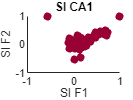


%Save figure
cd 'C:\SortingFolder\HIP\SI'
saveas(gcf,'SI_MUA.pdf');
saveas(gcf,'SI_MUA.tif');

saveas(gcf,'SI_MUA.fig');

% Significance SI Histogram
n= 1;
m= 1;
for i = 1: size(SignificanceWindowTableMUA,1)
    if SignificanceWindowTableMUA.SignificanceDEV1(i,1) > 0
        SI1HistIndx(n,1)=i;
        n = n + 1;
    end
    if SignificanceWindowTableMUA.SignificanceDEV2(i,1) > 0
        SI2HistIndx(m,1)=i;
        m = m + 1;
    end 
 end

% SI
figure
%Create histogram
histogram([NormalizedIndexesTableMUA.SI1(SI1HistIndx,1);NormalizedIndexesTableMUA.SI2(SI2HistIndx,1)],'BinWidth',0.1, 'FaceColor','#990033','FaceAlpha',1);
xlim([-1 1]);
ylim([0 100]);
xline(0,'LineWidth',2);
title('SI');
xlabel('SI index');
ylabel('repetitions');

%Calculating the mean and error
SI_Mean = mean([NormalizedIndexesTableMUA.SI1(SI1HistIndx,1);NormalizedIndexesTableMUA.SI2(SI2HistIndx,1)],"omitnan")

SI_Mean = 0.1258

SI_std = std([NormalizedIndexesTableMUA.SI1(SI1HistIndx,1);NormalizedIndexesTableMUA.SI2(SI2HistIndx,1)],"omitnan");
err_SI = SI_std / sqrt((size([NormalizedIndexesTableMUA.SI1(SI1HistIndx,1);NormalizedIndexesTableMUA.SI2(SI2HistIndx,1)],1))*2)

err_SI = 0.0105

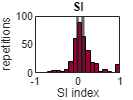

xline(SI_Mean,'LineWidth',2.5);

%Save figure
cd 'C:\SortingFolder\HIP\SI';
saveas(gcf,'SI_HIST_MUA.pdf');
saveas(gcf,'SI_HIST_MUA.tif');

saveas(gcf,'SI_HIST_MUA.fig');

% CSI
figure
%Create histogram
histogram(NormalizedIndexesTableMUA.CSI(SIscatterIndx,1),'BinWidth',0.1, 'FaceColor','#990033','FaceAlpha',1);
xlim([-1 1]);
ylim(rangoY);
xline(0,'LineWidth',2);
title('CSI');
xlabel('CSI index');
ylabel('repetitions');

%Calculating the mean and error
CSI_Mean = mean(NormalizedIndexesTableMUA.CSI(SIscatterIndx,1))

CSI_Mean = 0.1415

CSI_std = std(NormalizedIndexesTableMUA.CSI(SIscatterIndx,1));
err_CSI = CSI_std / sqrt(size(NormalizedIndexesTableMUA.CSI(SIscatterIndx,1),1))

err_CSI = 0.0229

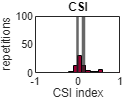

xline(CSI_Mean,'LineWidth',2.5);

%Save figure
cd 'C:\SortingFolder\HIP\CSI';
saveas(gcf,'CSI_MUA.pdf');
saveas(gcf,'CSI_MUA.tif');

saveas(gcf,'CSI_MUA.fig');

% iMM
iMMcasc = cat(1,NormalizedIndexesTableMUA.iMM1ca(SI1HistIndx,1),NormalizedIndexesTableMUA.iMM2cd(SI2HistIndx,1));
figure
%Create histogram
histogram(iMMcasc,'BinWidth',0.1,'FaceColor','#EA005F','FaceAlpha',1);
xlim([-1 1]);
ylim([rangoY]);
xline(0,'LineWidth',2);
title('iMM');
xlabel('iMM index');
ylabel('repetitions');

%Calculating the mean and error
iMMcasc_Mean = nanmean(iMMcasc)

iMMcasc_Mean = 0.1366

iMMcasc_std = nanstd(iMMcasc);
err_iMMcasc = iMMcasc_std / sqrt(size(iMMcasc,1))

err_iMMcasc = 0.0150

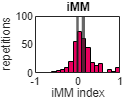

xline(iMMcasc_Mean,'LineWidth',2.5);

%Save figure
PathiMM = 'C:\SortingFolder\HIP\iMM';
cd (PathiMM);
saveas(gcf,'iMM_MUA.pdf');
saveas(gcf,'iMM_MUA.tif');

saveas(gcf,'iMM_MUA.fig');

% iPE CA1
iPEcasc = cat(1,NormalizedIndexesTableMUA.iPE1ca(SI1HistIndx,1),NormalizedIndexesTableMUA.iPE2cd(SI2HistIndx,1));
figure
%Create histogram
histogram(iPEcasc,'BinWidth',0.1,'FaceColor','#FF6600','FaceAlpha',1);
xlim([-1 1]);
ylim([rangoY]);
xline(0,'LineWidth',2);
title('iPE');
xlabel('iPE index');
ylabel('repetitions');

%Calculating the mean and error
iPEcasc_Mean = nanmean(iPEcasc)

iPEcasc_Mean = 0.1836

iPEcasc_std = nanstd(iPEcasc);
err_iPEcasc = iPEcasc_std / sqrt(size(iPEcasc,1))

err_iPEcasc = 0.0151

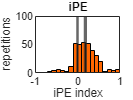

xline(iPEcasc_Mean,'LineWidth',2.5);

%Save figure
cd 'C:\SortingFolder\HIP\iPE';
saveas(gcf,'iPE_MUA.pdf');
saveas(gcf,'iPE_MUA.tif');

saveas(gcf,'iPE_MUA.fig');

% iRS CA1
iRScasc = cat(1,NormalizedIndexesTableMUA.iRS1ca(SI1HistIndx,1),NormalizedIndexesTableMUA.iRS2cd(SI2HistIndx,1));
figure
%Create histogram
histogram(iRScasc,'BinWidth',0.1,'FaceColor','#0099CC','FaceAlpha',1);
xlim([-1 1]);
ylim([rangoY]);
xline(0,'LineWidth',2);
title('iRS');
xlabel('iRS index');
ylabel('repetitions');

%Calculating the mean and error
iRScasc_Mean = nanmean(iRScasc)

iRScasc_Mean = -0.0470

iRScasc_std = nanstd(iRScasc);
err_iRScasc = iRScasc_std / sqrt(size(iRScasc,1))

err_iRScasc = 0.0115

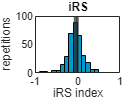

xline(iRScasc_Mean,'LineWidth',2.5);

%Save figure
cd 'C:\SortingFolder\HIP\iRS';
saveas(gcf,'iRS_MUA.pdf');
saveas(gcf,'iRS_MUA.tif');

saveas(gcf,'iRS_MUA.fig');